# Programação em Matlab

## Programação no Matlab: Conceitos Iniciais

- Linguagem de Programação

- Comando Edit 

- Toolboxs diversos

- Regressao Linear e Nao-Linear

- Resolução de Equações Diferenciais Parciais

- Projeto, Simulação e Controle de Sistemas

- Geração de Interface Gráfica (GUI)

- Computação Simbólica

- Data Science e Machine Learning

- e muito mais

## Alguns Comentários

A programação formal em Matlab apresenta um editor próprio com possibilidades de escrever `script`s, *function*s, `live scripts`, `live function`s, `class`, e `system object`s.

### Comando `edit` e Rudimentos

Na linha de comando, o editor de programação é lançado pelo comando `edit`. 

No diretório RUN, temos podemos rodar os scripts de diversas formas: 

- Rodar um script inteiro pelo botão `Run`.

- Rodar linha-por-linha pelo botão `Step`.

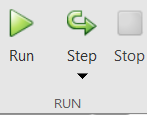

Temos ainda a diretório Section, possibilita rodar o scripts de seção-por seção. Uma seção em um script está relacionado ao duplo comentário `%%``.`

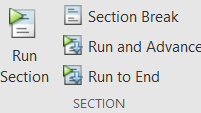

### Variável

Matlab não requer declaração de tipo (tipificação de variável). Contudo, aconselha-se a inicialização de algumas variáveis principais para o aumento da performance. Ainda, existem algumas variáveis convenientemente prédefinidas para o usuário, por exemplo:

- `pi` -> iqual a $\pi$

- `inf` -> resultado de uma divisão por zero

- `eps` -> precisão de máquina

- `realmax` -> maior número de ponto flutuante

- `realmin` -> menor número de ponto flutuante

- `NaN` -> 'Not-a-Number': resultado da divisão de zero por zero

- `i,j` -> ambos são o número imaginário $\sqrt{-1}$

No Matlab, as Instruções de atribuição assumem a forma:

`variable = [command] <expression>;`

onde `[...]` são opcionais. Se o ponto-e-virgula ; é omitido, o resultado da `expression,` armazenado na variable, é impresso. E caso não exista uma variável definida, o resultado será armazenado na variábel `ans`.

No Matlab, as variáveis são case-sensitives, ou seja, o interpretador faz diferença entre as variáveis `a` e `A`.

As variáveis podem ter comprimento máximo de 32 caracteres, mas não aceitam **espaços** ou **hifens**. Uma alternativa é utilizar a tecla underscore (sublinhada) como substitua. Por exemplo, a variável `test user` e `test-user` não são aceitos, mas a `test_user` sim.

É necessário evitar utilizar comandos do Matlab, ou ainda a palavra Matlab, como variáveis.

### Expressões Matemáticas

É válido o uso de variávies, constantes, operadores e funções em expressões matemáticas no Matlab.

A precedência nas operações matemáticas segue a sequência usual aceita por outras linguagens de programação. A lista abaixo apresenta da maior precedência para a menor:

- Cochetes `[...]`, e parêntesis` (...) `(prefira o ultimo);

- Elevação a potência `^` ;

- Multiplicação `*` e Divisão `/`;

- Soma `+` e Subtração `-` ;

Sabendo que a precedência prioriza as operações da **esquerda** para a **direita**.

## Laços

Laços são estrutura de linguagem para realizar conjunto de declarações repetidas vezes: (a) um número fixo de repetições (`for-end`), ou (b) até uma condição ser alcançada (`while-end`);

### Laço '`for-end`'

Para a execução de repetições de um ou mais declarações (linhas de código), o laço `for-end` é utilizado. O laço `for-end` apresenta a seguinte forma:

Por exemplo, ao atribuir valores a um vetor, em um loop `for-end`, observa-se que a geração de um vetor linha.

***Vamos executar as linhas de código acima?***

O resultado experado é um vetor linha `d = 1 8 27 64`.

### Laço '`while-end`'

O laço `while-end` é usada quando a repetição está sujeita a uma condição. O laço `while-end` apresenta a seguinte forma:

A condição <loop_condicao> é uma expressão de relacional do tipo $e_1 \bullet e_2$, onde $e_i \;\left(i=1,2\right)$ são expressões aritméticas já descritas, e $\bullet \;$é um operador relação definido abaixo:

- `==` $\longrightarrow$ igual

- `~=` $\longrightarrow$ diferente

- `<=` $\longrightarrow$ menor do que ou igual

- `>=` $\longrightarrow$ maior do que  ou igual

- `<`   $\longrightarrow$ menor do que

- `> ` $\longrightarrow$ maior do que

As expressões de relação podem ser combinadas com os seguintes operadores lógicos:

- `&  `$\longrightarrow$ operador '`e`'

- `|  `$\longrightarrow$ operador '`ou`'

- `~  `$\longrightarrow$ operador 'falso'

- `&& `$\longrightarrow$ operador   'e' escalar* 

- `|| `$\longrightarrow$ operador 'ou' escalar*

`OBS: * - Quando a primeiro declaração é falsa, a segunda não é avaliada.`

Por exemplo, ao atribuir valores a um vetor, em um loop `for-end`, observa-se que a geração de um vetor linha.

***Vamos executar as linhas de código acima?***

## Condição '`if-else-end`'

A condição `if-else-end` é uma estrutura de programação vital para a mudança na sequência de instruções executadas em um programa. A declaração `if-else-end` apresenta a seguinte forma: 

Por exemplo:

Ou ainda,

***Vamos executar as linhas de código acima?***

OBS: Existe ainda o comando `switch-case-end` para determinar escolhas. Por conta do tempo limitado para o presente curso não apresentaremos essa estrutura de programação.

## Funções Definidas pelo Usuário

O Matlab possibilita ao usuário definir suas próprias funções, mas uma sintaxe específica deve ser seguinda:

E para executar uma função em um script Matlab, devemos escrever da seguinte forma

### Exemplo:

Seja a serie de Fourier de um função 'Dente-de-Serra',


$$y\left(t\right)=\frac{1}{2}-\sum_{n=1}^{\infty } \sin \left(2\pi \frac{\mathrm{nt}}{T}\right)$$


onde, $T$é o período da forma de onda. A função sawblade pode ser definida pelas linhas de código:

Essa linha de código já está escrita no final desse live script. Para observarmos o seu funcionamento, temos as seguinte linhas:

***Use '***`Crlt+Enter`***' para executar as linhas de código abaixo:***



f = @(x) (x/2.4).^3-2*x/2.4+cos(pi*x/2.4);

solution = fzero(f,2.9)

Outra forma simples de funções definidas por usuário são as funções anônimas (`function_handle`). Por exemplo, dada a expressão:


$${f\left(x\right)=\left(\frac{x}{2\ldotp 4}\right)}^3 -2\frac{x}{2\ldotp 4}+\cos \left(\pi \frac{x}{2\ldotp 4}\right)$$
 

A definição da função anônima em Matlab é dada pelas seguintes linhas

f = @(x) (x/2.4).^3-2*x/2.4+cos(pi*x/2.4)
f([1 2])

A raiz da função f(x) é dada pelo comando `fzero`, ou seja:

solution = fzero(f,2.9)

Podemos ainda plotar a 

x = 0:0.1:5; plot(x,f(x))
hold on; plot(solution,f(solution),'r*'); hold off;

## Estrutura de Dados em Matlab

Existem muitos tipos de dados ou classes diferentes com os quais podemos trabalhar no MATLAB®. Você pode construir matrizes e arrays de dados de ponto flutuante e inteiros, caracteres e strings, valores lógicos `verdadeiros` e `falsos` e assim por diante. As funções anônimas (functions handles) conectam seu código a qualquer função MATLAB, independentemente do escopo atual. Tabelas, horários, estruturas e matrizes de células fornecem uma maneira de armazenar tipos diferentes de dados no mesmo contêiner.

Existem 16 classes fundamentais no MATLAB. Cada uma dessas classes está na forma de uma matriz ou array. Com exceção das funções anônimas, essa matriz ou vetor tem tamanho mínimo de 1-por-1 e pode crescer até um vetor n-dimensional de qualquer tamanho. Um  função anônima é sempre escalar (1-por-1).

Todas as classes fundamentais do MATLAB são mostradas no diagrama abaixo:

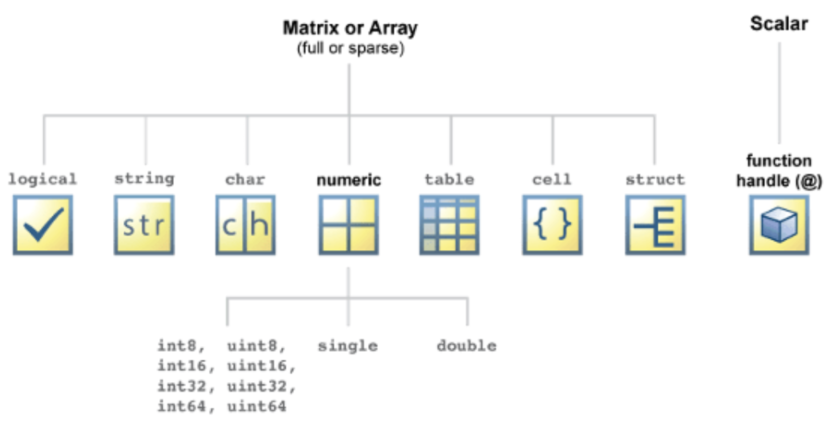

### Células (`cell`)

Nas seções anteriores, foram discutidas algumas dessas estruturas de dados. Agora vamos introduzir a estrutura de celula, que nos permitirá desenvolver estruturas de dados mais complexas. Dados em célula são indicadas por cochetes, ou seja, `{...}`. Por exemplo:

A = cell(4,1);
A = {'maths';'physics';'history';'IT'}
p = A(2)
cont = A{3}
cont(4)

Outro exemplo, celulas possibilita agrupar dados numéricos e texto (*string*) de tamanhos e formas diferentes. Por exemplo:

***Vamos executar as linhas de código acima?***

Podemos explorar com mais detalhe o conteudo de uma célula pelo comando `celldisp`:

***Vamos executar as linhas de código acima?***

### Estrutura (`structure`)

A última forma de dados é a estrutura, usando `struct`. Semelhante a uma matriz de células, mas o endereçamento é indexado por nomes . Uma estrutura combina vários campos, cada um dos quais pode ser de um tipo diferente. Por exemplo:

names = {'A Best', 'D Good', 'S Green', 'J Jones'}
fees = {333 450 200 800}
subjects = {'cs', 'cs', 'maths', 'eng'}

StudentRecords = struct('NameField',names,'FeeField',fees,...
                                'SubjectFields',subjects)

Agora, através da estrutura, podemos nos referir a cada registro individulamente usando um campo:

StudentRecords(1)

Ou ainda, examinar o conteúdo de um único componente do registro:

StudentRecords(1).NameField
StudentRecords(2).SubjectFields

Ou atualizar os valores de cada um dos componentes.

StudentRecords(3).FeeField = 1000;
StudentRecords(3).FeeField

MATLAB proporciona um conjunto de funções para converter de uma estrutura para outra, e vice-versa:

##  Armadilhas em MATLAB

### **É importante tomar cuidado ao nomear arquivos e funções**. 

Nomes de arquivos e função os nomes seguem as regras para nomes de variáveis; isto é, eles devem começar com uma letra seguida por uma combinação de letras ou dígitos e nomes de funções existentes não devem ser usados.

### Não use nomes de funções ou comandos MATLAB para nomes de variáveis. 

Por exemplo, se fomos tão tolos ao atribuir um número a uma variável que chamamos de `sin`, acesso ao a função senoidal seria perdida.

### Os tamanhos das matrizes são definidos por atribuição.

É vital garantir que os tamanhos das matrizes sejam compatível. Muitas vezes é uma boa ideia atribuir inicialmente uma matriz a um matriz dimensionada de zeros; isso também torna a execução mais eficiente. 

Por exemplo, considere o seguinte script simples:

***Vamos executar as linhas de código acima?***

### Tome cuidado com produtos escalares.

Por exemplo, ao criar uma função definida pelo usuário onde qualquer um dos parâmetros de entrada puder ser vetores, produtos escalares devem ser usados. 

Nota-se que `2.^x` e `2. ^x` são diferentes porque o espaço é importante. O primeiro exemplo dá a potência do ponto enquanto o segundo dá `2.0` à potência `x`, não o potência escalar.

Cuidado semelhante com espaços deve ser tomado ao usar números complexos. Para por exemplo, `A = [1 2-4i]` atribui dois elementos: o número inteiro $1$ e o número complexo$2-\jmath 4$. Em contraste `B = [1 2 -4i]` atribui três elementos: os números $1$, $2$ e o número imaginário $-4\jmath$.

### Inicializar variáveis

No início de um script, geralmente é uma boa prática limpar variáveis ou definir arrays iguais à matriz vazia (por exemplo, `A = [ ]`). Isso evita incompatibilidade em operações matriciais.

## Exemplo de Aplicação: Vibração Livre de Massa-Mola

Um sistema massa-mola amortecido apresenta a seguinte equação de movimento :

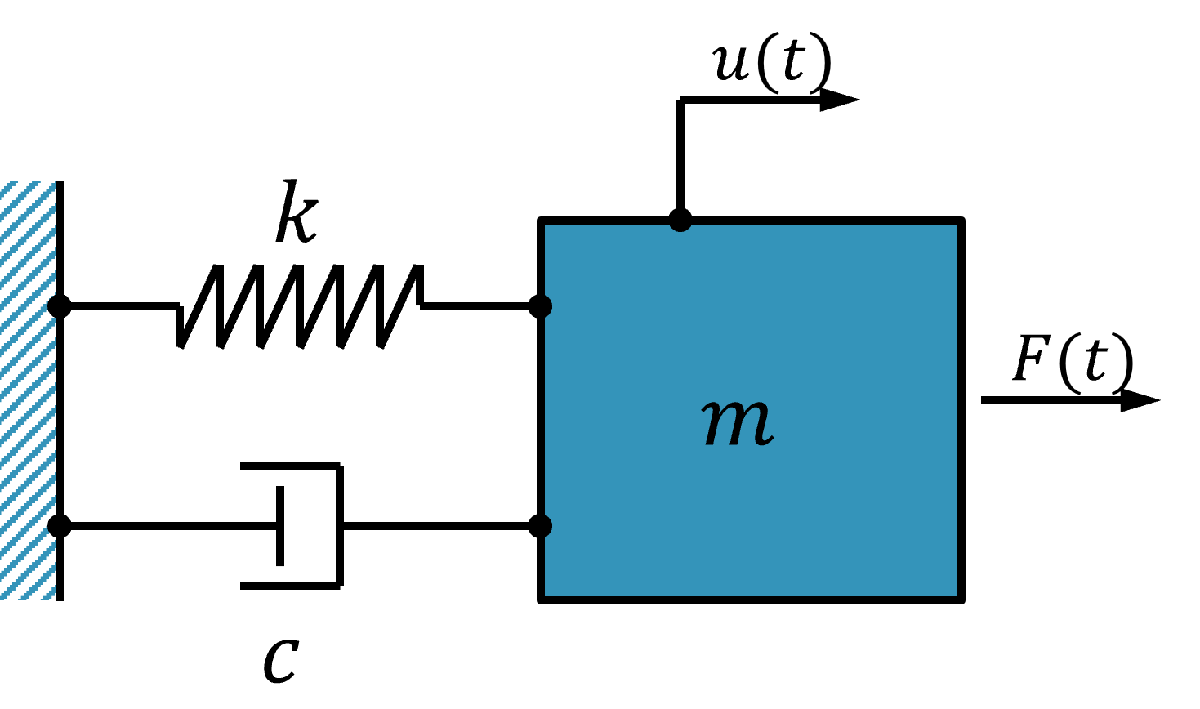

$m\ddot{\;u} \left(t\right)+c\dot{u} \left(t\right)+k\;u\left(t\right)=F\left(t\right)$,

onde, $m$, $c$ e $k$ são, respectivamente, a massa $m\;\left\lbrack \textrm{kg}\right\rbrack$, coef. de amortecimento $c\;\left\lbrack N\;s/m\right\rbrack$, e coef. de rigidez $k\;\left\lbrack N/m\right\rbrack$, e $F\left(t\right)$ é a função de forçamento.

Dividindo a expressão pela massa $m$, a equação de movimento do sistema massa mola amortecido é descrito por:

$\ddot{u} \left(t\right)+2\xi \;\omega_n \;\dot{u} \left(t\right)+\omega_n^2 \;u\left(t\right)=\omega_n^2 \;f\left(t\right)$,

onde, $\omega_n =\sqrt{\;k/m}$ é a frequência natural do massa-mola, $\xi =c/c_c$ é a razão da amortecimento com relação a amortecimento crítico $c_c =2\xi \;\omega_n m$, e $f\left(t\right)=F\left(t\right)/k\;$ é a representação em deslocamento estático equivalente $\left\lbrack m\right\rbrack$ da função forçamento.

Esse tipo de problema é conhecido como um Problema de Valor Inicial (PVI - ingl. *Initial Value Problem*). A equação de movimento fica necessida de condições iniciais de deslocamento $u\left(t=0\right)=u_o$ e velocidade $\dot{\;u} \left(t=0\right)=v_o$.

Logo, a PVI do massa mola amortecido é descrito pela expressão: 


$$\left\lbrace \begin{array}{l}
\ddot{u} \left(t\right)+2\xi \;\omega_n \;\dot{u} \left(t\right)+\omega_n^2 \;u\left(t\right)=\omega_n^2 \;f\left(t\right)\\
u\left(t=0\right)=u_o \\
\dot{\;u} \left(t=0\right)=v_o 
\end{array}\right.$$


### Vibração Livre Amortecido

Supondo $F\left(t\right)=0$, ou seja, o caso em vibração livre:


$$\left\lbrace \begin{array}{l}
\ddot{u} \left(t\right)+2\xi \;\omega_n \;\dot{u} \left(t\right)+\omega_n^2 \;u\left(t\right)=0\\
u\left(t=0\right)=u_o \\
\dot{\;u} \left(t=0\right)=v_o 
\end{array}\right.$$


### Integração de Sistema de EDOs

As técnicas de integração temporal de equações diferenciais soluciona equações diferencias ordinárias de 1º ordem:


$$\frac{\textrm{du}\left(t\right)}{\textrm{dt}}=F\left(u,t\right)$$


A solução da equação de movimento do massa-mola amortecido, uma equação diferencial de 2º ordem precisa ser transformada em duas equações diferenciais de 1º ordem. Para tanto, efetua-se a seguinte transformação de variável:

$v\left(t\right)=\dot{\;u} \left(t\right)$.

Substituindo na equação de movimento do massa-mola, temos:


$$\dot{v} +2\xi \;\omega_n \;v+\omega_n^2 \;u=0$$


ou seja, temos a seguinte sistema de equações diferenciais ordinárias:

$\left\lbrace \begin{array}{l}
\dot{u} =v\\
\dot{v} =-2\xi \;\omega_n \;v-\omega_n^2 \;u
\end{array}\right.$,

Em forma matricial, 

$\left\lbrack \begin{array}{c}
\dot{u} \\
\dot{v} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
v\\
-2\xi \;\omega_n \;v-\omega_n^2 \;u
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
-\omega_n^2  & -2\xi \;\omega_n 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u\\
v
\end{array}\right\rbrack$, ou ainda, $\dot{\mathit{\mathbf{z}}} =\textrm{Az}$,

onde, $z={\left\lbrack \begin{array}{cc}
u & v
\end{array}\right\rbrack }^T$ é o vetor de estado e $\mathit{\mathbf{A}}$é a matriz de estado. Essa sistema é denominado como Equação de Estado.

Para programar a função de Equação de Estado temos o seguinte código:

Essa função está funcionando no final desse Live Editor (seção HELPER FUNCTION).

### Comando ode45

A solução de equações diferenciais no Matlab utiliza a família `ode`:

- ode23 - Runge-Kutta 2º Ordem Erro 3ºOrdem

- ode45 - Runge-Kutta  4º Ordem Erro 5ºOrdem

- ode15 - Gear Method 1º Ordem até 5ºOrdem

- entre outros

*Ref: Shampine, L. F. and M. W. Reichelt, “*[*The MATLAB ODE Suite*](https://www.mathworks.com/help/pdf_doc/otherdocs/ode_suite.pdf)*,” SIAM Journal on Scientific Computing, Vol. 18, 1997, pp. 1–22.*

Como não é o propósito dessa apresentação uma discussão mais profunda sobre os métodos, vamos apenas nos limitar a utilizar comando ode45 e descrever a sua sintaxe.

O comando ode45 apresenta a seguinte sintaxe, conforme descrita na ajuda online:

Logo,

onde, `odefun` é a equação de estado, `tspan` é o intervalo de tempo a ser calculado, e `y0` são as condições inicias do PVI. O resultado da integração no tempo é armazenado na variável de tempo `t` e no vetor solução `y` $\left\lbrack 2,n\right\rbrack$.

Logo, para o presente caso, temos as seguinte linhas:

onde, `@(t,z) GDL1L_dampV(t,z,omg,xi)` é a forma de chamar a função GDL1_dampV

Vc pode tentar as seguinte linhas de comando.

***Vamos executar as linhas de código acima?***

omg = 2*pi/1 ; % frequência natural wn = 2pi f, onde f (Hz)
xi  = 0.01   ; 

% condições iniciais
u0 = 1.0;
v0 = 0.0;

% integração ode45
T = 2*pi/omg ;
Nper = 20; Dper = 20 ;
tt = linspace(0,Nper*T,Dper*Nper) ;

[t1,z1] = ode45(@(t,z) GDL1L_dV(t,z,omg,xi),tt,[u0 v0]);

### Movimento do Massa-Mola

Sabendo que a solução analítica de um sistema massa-mola amortecido é descrito pela seguinte expressão:

$u\left(t\right)=\;\exp \left(-\xi \omega_n t\right)\left(u_o \;\cos \left(\omega_d \;t\right)+\left(\frac{v_o +u_o \;\xi \;\omega_n }{\omega_d }\right)\sin \left(\omega_d \;t\right)\right)$,

ou ainda,

$u\left(t\right)=A\;\exp \left(-\xi \omega_n t\right)\cos \left(\omega_d \;t-\phi \;\right)$,

onde, $\omega_d =\omega_n \sqrt{\;1-\xi^2 }$ é a frequência amortecida, $A=\sqrt{\;u_o^2 +{\left(\frac{v_o +u_o \;\xi \;\omega_n }{\omega_d }\right)}^2 }$ é a amplitude de oscilação, e $\tan \;\phi =\frac{v_o +u_o \;\xi \;\omega_n }{\omega_d \;u_o }$ é o angulo de fase,

Para verificar a solução numérica, compara-se com a solução analítica,

***Vamos executar as linhas de código acima?***

% solução analítica
omg_d = omg * sqrt(1-xi^2) ;
u_anal = exp(-xi*omg*t1).*(u0*cos(omg_d*t1)+(v0+u0*xi*omg)/omg_d*sin(omg_d*t1)) ;
v_anal = -xi*omg*t1.*exp(-xi*omg*t1).*(u0*cos(omg_d*t1)+(v0+u0*xi*omg)/omg_d*sin(omg_d*t1)) + ...
 omg_d.*exp(-xi*omg*t1).*(-u0*sin(omg_d*t1)+(v0+u0*xi*omg)/omg_d*cos(omg_d*t1));


% plotagem por subplot
close all
subplot(2,1,1);
plot(t1,z1(:,1),'r.')
hold on ;
plot(t1,u_anal,'b-')
ylabel('deslocamento ${u}(t)$ [m]',"Interpreter","latex")
legend('ode45','analítico')
subplot(2,1,2);
plot(t1,z1(:,2),'r.')
hold on;
plot(t1,v_anal,'b-')
xlabel('t [s]',"Interpreter","latex")
ylabel('velocity $\dot{u}(t)$ [m/s]',"Interpreter","latex")
legend('ode45','analítico')

## Exemplo de Aplicação: Decaimento Logaritmico

O movimento de um sistema massa-mola amortecido está contido dentro de uma envoltória exponência, conforme expressão:

$e\left(t\right)=A\;\exp \left(-\xi \omega_n t\right)$,

Podemos observa a partir das linhas de comando abaixo:

***Vamos executar as linhas de código acima?***

% solução analítica
omg_d = omg * sqrt(1-xi^2) ;
A = sqrt(u0^2+((v0+u0*xi*omg)/omg_d)^2);
u_anal_envolv = A*exp(-xi*omg*t1);


% plotagem por subplot
figure()
plot(t1,z1(:,1),'r.')
hold on ;
plot(t1,u_anal,'b-')
plot(t1,(+1)*u_anal_envolv,'b--')
plot(t1,(-1)*u_anal_envolv,'b--')
xlabel('t [s]',"Interpreter","latex")
ylabel('deslocamento ${u}(t)$ [m]',"Interpreter","latex")
legend('ode45','analítico','envoltoria')

Uma forma de estimar os picos máximos e mínimos pode ser realizada pelo comando `findpeaks`:

[~,LOCS_max]= findpeaks(z1(:,1));
[~,LOCS_min]= findpeaks(1.01*max(z1(:,1))-z1(:,1));
plot(t1(LOCS_max,1),z1(LOCS_max,1),'ko')
plot(t1(LOCS_min,1),z1(LOCS_min,1),'ks')
legend('ode45','analítico','envoltoria','peaks_{max}','peaks_{mim}')

Com os mínimos e os máximos, podemos ajustar a envoltoria exponêncial com o comando `polyfit`:

fkd

p_max = polyfit(t1(LOCS_max,1),log(+1*z1(LOCS_max,1)),1) 
p_min = polyfit(t1(LOCS_min,1),log(-1*z1(LOCS_min,1)),1) 
% plot
figure()
plot(t1(LOCS_max,1),log(+1*z1(LOCS_max,1)),'ro')
hold on
plot(t1(LOCS_min,1),log(-1*z1(LOCS_min,1)),'rs')
plot(t1,polyval(p_max,t1))
% estimativa do amortecimento
omg_est = sqrt(omg_d^2+p_max(1)^2)
xi_est  = -1*p_max(1)/omg_est
xi

Outra forma de realizar a estimativa é pela Toolbox `CFTOOL`:

cftool

## Lecture 2 - Comentários Finais

bla bla bla

## HELPER FUNCTION

function dz = GDL1L_dV(~,z,omg,xi)
 dz = zeros(2,1);
 dz = [0 1;(-1*omg*omg) (-2*xi*omg)]*z ;
end

function y = sawblade(t,T,n_trms)
% Avalia, no instante t, a aproximação de Fourier da função 'dente-de-serra'
% de período T usando os primeiros termos n_trms da série infinita.
   y = 1/2; 
   for n = 1:n_trms
      y = y - (1/(n*pi))*sin(2*n*pi*t/T);
   end
end